### Part-2

### Creation and STFT on a Sinusoidal Signal

clc
clear all
%Creation of a sinusoidal signal for Part-2 Implementations
sep= 500e3;  
f= 8000;  
cycles=10;  
t=0:1/sep:cycles*1/f;% Time variable for the creation of continous sinusoidal signal
A= 2; %Amplitude
p= pi/6; %Phase, in radians
sin_sig= A*cos(2*pi*f.*t+p);

#### a.Obtain 3 spectrogram plots for a signal with known frequency.

win_len1=80;
win_type='rectangular';
shift1=win_len1/2;
num_fft1=win_len1*2;

win_sig1 = ones(1, win_len1);
% lengths of signals
in_len1 = length(sin_sig);
% number of segments/frames
num_seg = 1+fix((in_len1-win_len1)/shift1);


[s1, freqs1, time1] = spectrogram(sin_sig,win_sig1,shift1,num_fft1,[],[],f, 'yaxis')

s1 =    6.6279 + 0.0000i  18.8490 + 0.0000i -30.6575 + 0.0000i  20.2346 + 0.0000i   4.8614 + 0.0000i -26.4322 + 0.0000i  28.8356 + 0.0000i -10.3289 + 0.0000i -15.6679 + 0.0000i  30.3030 + 0.0000i -22.9639 + 0.0000i  -1.0276 + 0.0000i  24.2739 + 0.0000i -29.9179 + 0.0000i
 -29.2763 + 1.9511i  23.4730 + 7.6446i  -0.6482 -11.6968i -22.6466 + 7.2671i  29.5192 + 2.4324i -14.9859 -10.3681i -10.4145 +10.7853i  28.2628 - 3.3815i -25.6163 - 6.4744i   4.3941 +11.6353i  20.0145 - 8.3589i -29.9095 - 0.9790i  18.1156 + 9.6070i   6.8149 -11.2684i
  14.6366 +60.6283i  50.2281 -46.5471i -78.6697 - 1.2877i  50.0639 +48.1888i  14.8459 -60.1457i -68.9901 +28.4878i  73.1060 +23.8281i -24.2090 -58.8650i -42.2433 +51.2158i  78.0627 - 6.4274i -57.2748 -43.0218i  -5.0460 +61.2737i  63.7078 -35.0928i -76.1717 -16.5357i
  67.2246 -13.2740i -50.6152 -52.0090i  -2.6979 +79.5775i  54.0547 -49.4402i -66.2136 -16.5487i  30.3576 +70.5373i  27.5123 -73.3757i -65.4315 +23.0055i  55.9030 +44.0472i  -5.8363 -79.1589i -48

freqs1 =          0
    0.0063
    0.0125
    0.0188
    0.0250
    0.0312
    0.0375
    0.0438
    0.0500
    0.0563


time1 =     40    80   120   160   200   240   280   320   360   400   440   480   520   560


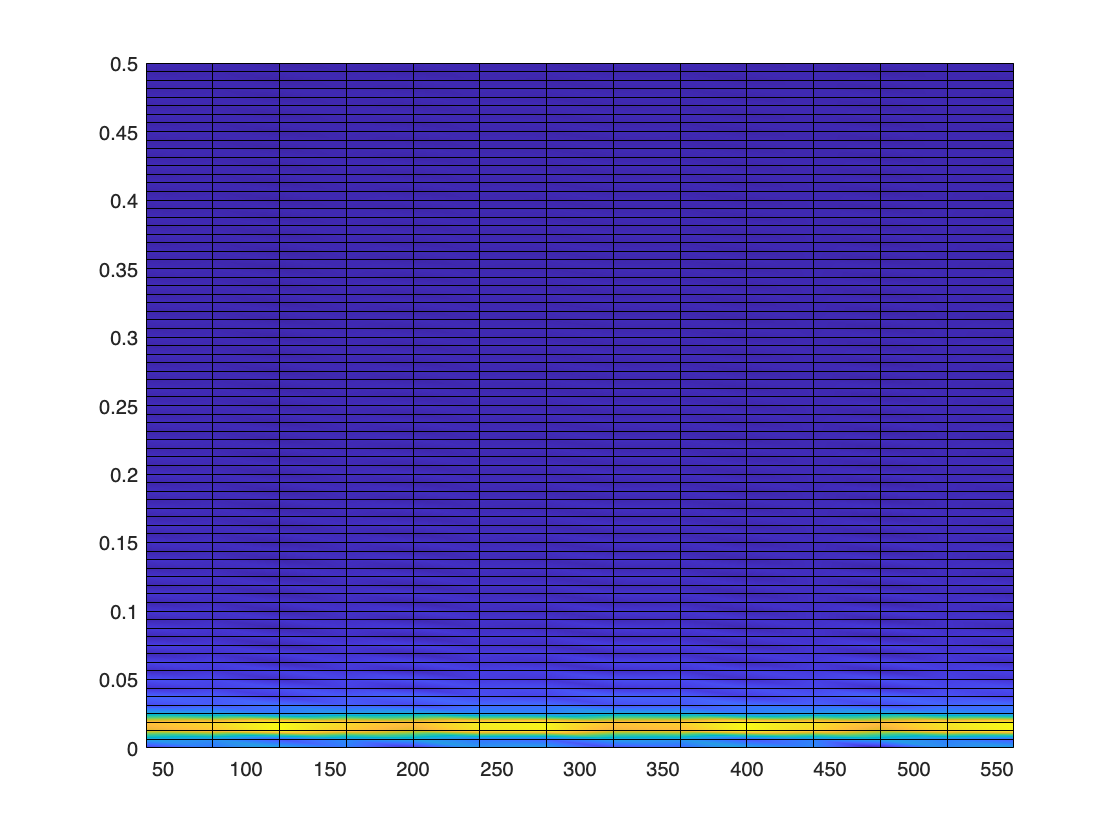

mag_stft1 = abs(s1);

s=pcolor(time1,freqs1.',mag_stft1);
s.FaceColor='interp';

win_len2=110;
win_type='rectangular';
shift2=win_len2/2;
num_fft2=win_len2*2;

win_sig2 = ones(1, win_len2);
% lengths of signals
in_len2 = length(sin_sig);
% number of segments/frames
num_seg2 = 1+fix((in_len2-win_len2)/shift2);



[s2, freqs2, time2] = spectrogram(sin_sig,win_sig2,shift2,num_fft2,[],[],f, 'yaxis')

s2 = 1.0e+02 *

  -0.2618 + 0.0000i  -0.1392 + 0.0000i   0.0589 + 0.0000i   0.2250 + 0.0000i   0.2692 + 0.0000i   0.1675 + 0.0000i  -0.0251 + 0.0000i  -0.2040 + 0.0000i  -0.2724 + 0.0000i  -0.1931 + 0.0000i
   0.0862 + 0.0873i   0.2707 + 0.0496i   0.3084 - 0.0150i   0.1790 - 0.0715i  -0.0475 - 0.0892i  -0.2482 - 0.0586i  -0.3144 + 0.0038i  -0.2102 + 0.0641i   0.0080 + 0.0897i   0.2218 + 0.0667i
  -0.3882 + 0.0522i  -0.2111 + 0.1905i   0.0805 + 0.2255i   0.3285 + 0.1383i   0.3984 - 0.0239i   0.2523 - 0.1731i  -0.0305 - 0.2285i  -0.2968 - 0.1600i  -0.4022 - 0.0048i  -0.2896 + 0.1530i
   0.2562 + 0.8797i   0.8908 + 0.5001i   1.0425 - 0.1507i   0.6291 - 0.7198i  -0.1253 - 0.8987i  -0.8118 - 0.5904i  -1.0582 + 0.0378i  -0.7311 + 0.6456i  -0.0076 + 0.9034i   0.7199 + 0.6715i
   0.9136 - 0.2426i   0.5289 - 0.8847i  -0.1425 - 1.0473i  -0.7366 - 0.6422i  -0.9315 + 0.1110i  -0.6214 + 0.8041i   0.0255 + 1.0613i   0.6586 + 0.7432i   0.9347 + 0.0222i   0.7041 - 0.7107i
  -0.0509 - 0.3938i  -0.2295 

freqs2 =          0
    0.0045
    0.0091
    0.0136
    0.0182
    0.0227
    0.0273
    0.0318
    0.0364
    0.0409


time2 =     55   110   165   220   275   330   385   440   495   550


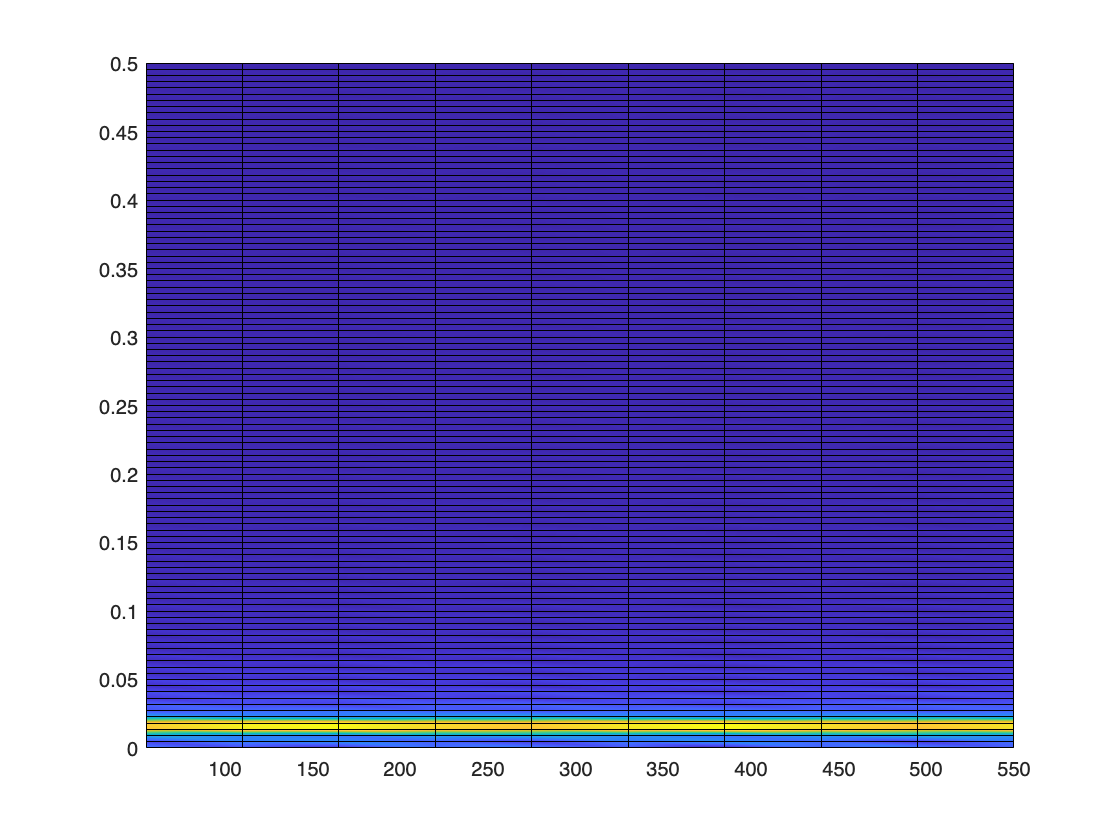

mag_stft2 = abs(s2);

snew=pcolor(time2,freqs2.',mag_stft2);
snew.FaceColor='interp';

win_len3=140;
win_type='rectangular';
shift3=win_len3/2;
num_fft3=win_len3*2;

win_sig3 = ones(1, win_len3);
% lengths of signals
in_len3 = length(sin_sig);
% number of segments/frames
num_seg3 = 1+fix((in_len3-win_len3)/shift3);



[s3, freqs3, time3] = spectrogram(sin_sig,win_sig3,shift3,num_fft3,[],[],f, 'yaxis')

s3 = 1.0e+02 *

   0.0918 + 0.0000i  -0.1087 + 0.0000i  -0.2503 + 0.0000i  -0.2562 + 0.0000i  -0.1232 + 0.0000i   0.0766 + 0.0000i   0.2348 + 0.0000i
  -0.2878 + 0.0197i  -0.2797 - 0.0303i  -0.1200 - 0.0639i   0.1048 - 0.0629i   0.2727 - 0.0277i   0.2928 + 0.0224i   0.1542 + 0.0604i
   0.1114 + 0.1455i  -0.1389 + 0.1361i  -0.3138 + 0.0530i  -0.3187 - 0.0589i  -0.1508 - 0.1388i   0.0989 - 0.1435i   0.2949 - 0.0704i
  -0.4990 + 0.1018i  -0.4773 - 0.1566i  -0.1969 - 0.3302i   0.1902 - 0.3248i   0.4742 - 0.1433i   0.5012 + 0.1159i   0.2564 + 0.3122i
   0.4012 + 1.1481i  -0.5848 + 1.0743i  -1.2538 + 0.4181i  -1.2432 - 0.4648i  -0.5587 - 1.0956i   0.4287 - 1.1326i   1.1836 - 0.5556i
   1.1349 - 0.3809i   1.0515 + 0.5859i   0.3980 + 1.2351i  -0.4712 + 1.2147i  -1.0850 + 0.5360i  -1.1107 - 0.4333i  -0.5343 - 1.1677i
  -0.0861 - 0.4397i   0.1650 - 0.4114i   0.3266 - 0.1601i   0.3113 + 0.1780i   0.1272 + 0.4196i  -0.1259 + 0.4338i  -0.3107 + 0.2128i
   0.1971 - 0.0908i   0.1740 + 0.1396i   0.056

freqs3 =          0
    0.0036
    0.0071
    0.0107
    0.0143
    0.0179
    0.0214
    0.0250
    0.0286
    0.0321


time3 =     70   140   210   280   350   420   490


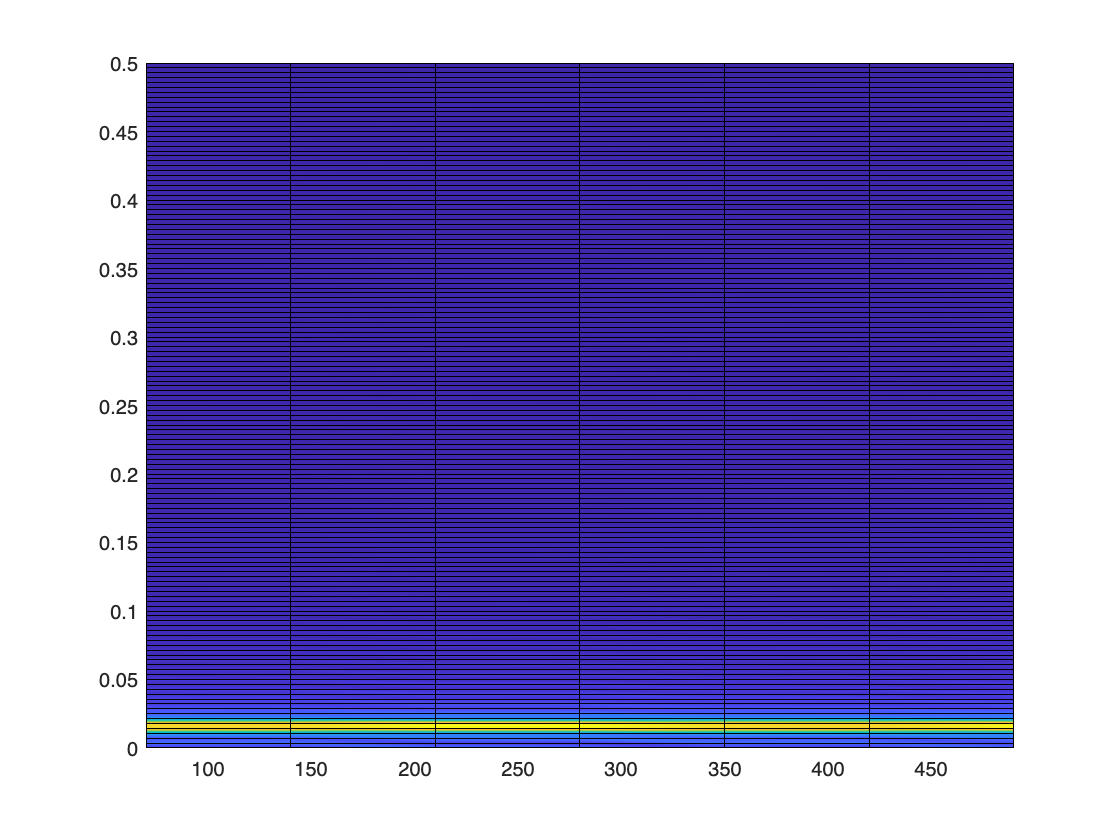

mag_stft3 = abs(s3);

snew2=pcolor(time3,freqs3.',mag_stft3);
snew2.FaceColor='interp';